# Edge Detection - Applied 

[⇦ Main Menu](matlab:open('../../MainMenu.mlx'))

This script serves as an introduction and application of gradient estimation for edge detection.

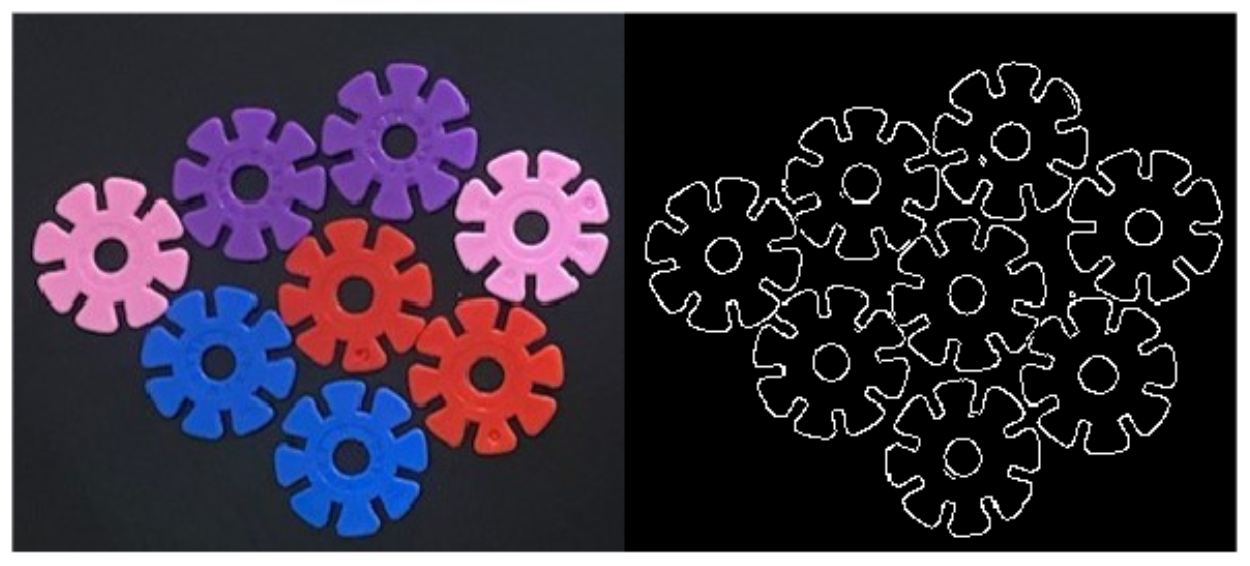

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Overview of Edge Detection

Edge detection aims to identify authentic edges while minimizing false edges caused by noise. Reliable edge detectors maximize authentic edge detection and minimize false positives, ensuring a realistic edge representation.

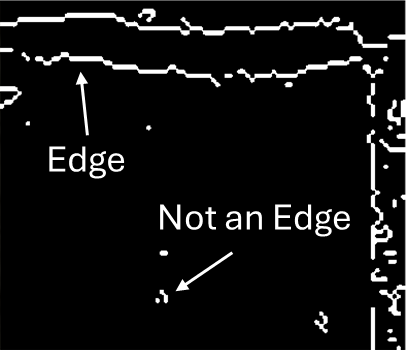

## Gradient Estimation with Convolution Kernels (2D) 

The overall image gradient provides an overall picture/understanding of the edges and transitions in images. We explored this concept in [EdgeDetectionTheory.mlx](matlab:open('../../Scripts/EdgeDetectionTheory.mlx')). We learned that the greater the **edge strength**, as measured by the magnitude of the **gradient vector**, the greater the likelihood of effective edge detection. We also learned the concept of **edge direction**, which is determined by the orientation of the **gradient vector**.

Gradient estimation in images involves calculating the rate of change in intensity at each pixel to identify edges—two **convolution kernels**, known as and are used to approximate the gradient. The kernel provides the rate of change in intensity or color along the horizontal axis of an image, thus highlighting vertical edges. Conversely, the kernel provides the rate of change in intensity along the vertical axis, therefore capturing the vertical components. Convolution involves sliding these [**convolution kernels**](about:blank<#M_3e7e%3E) over the image and performing element-wise multiplication and summation at each position. These convolutions highlight intensity changes, with gradient magnitude showing **edge strength** and **edge direction** indicating orientation, effectively identifying significant edges for analysis.

Each of these edge operators has its strengths and is chosen based on the specific requirements of the task at hand. For instance, if you need quick and simple edge detection in a clean image, the Roberts operator might be sufficient. For more noisy images, the Sobel operator would be a better choice due to its noise-reducing properties.

  **Try**. Visualize the directional gradients of 2D images by selecting the method and then pressing the button. 

Method = "Select";
Image = "Select";
 

if ~strcmp(Method,"Select")&&~strcmp(Image,"Select")
    INew = imread(Image); %#ok<*UNRCH>
    ImGr = im2gray(INew);

    [~,~,Gx,Gy] = edge(ImGr,Method);

    GxAnnotated = insertText(Gx,[10,10],"Gx",TextColor="white",BoxColor="black",FontSize=36);
    GyAnnotated = insertText(Gy,[10,10],"Gy",TextColor="white",BoxColor="black",FontSize=36);

    ImageAnnotated = insertText(INew,[10,10],"Original Image",FontSize=36);

    montage({ImageAnnotated,GxAnnotated,GyAnnotated},Size=[1,3]);
else
    warning("Select a valid option.")
end

 **Exercise 1. **Compare the gradients in the x and y directions. Which gradient identifies horizontal lines?

**Solution:**

CheckAnswer("exercise1","Select");  

 **Exercise 2. **Which gradient would be most effective for finding the edges in the following image?

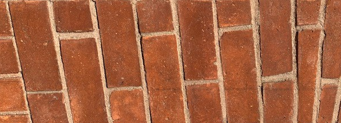

**Solution:**

CheckAnswer("exercise2","Select"); 

## Optimal Edge Detection - The Canny Method

The most widely used method for edge detection is the Canny method. It starts by converting the image to grayscale and applying a Gaussian filter to suppress noise. Then, it computes the gradient magnitude and direction. Non-maximum suppression is performed to thin out the edges, followed by double thresholding to identify potential edges. Finally, edge tracking by hysteresis is used to confirm strong edges and discard weak ones.

The steps of the Canny method include:

### **1. Suppress noise**: 

Here, a Gaussian filter is applied, which smooths the image by averaging each pixel with its neighbors according to a Gaussian distribution. The size of the **convolution kernel**) determines the level of smoothing. You will notice that the edges become less defined after noise suppression. Small sigma (smoothing factor) values for the Gaussian filter help us to detect fine-scale edges, whereas large sigma values detect large-scale edges. 

ImGauss = imread("BrickAngled.jpg");
ImGaussG = im2gray(ImGauss);

% Smooth the image with a Gaussian filter
sigma = 2; % Standard deviation for Gaussian filter
ISmoothed = imgaussfilt(ImGauss,0.5);

ISmoothedAnnotated = insertText(ISmoothed,[10,10],"Smoothed Image",BoxColor="black",fontsize=36,TextColor="white");
ImGaussAnnotated = insertText(ImGauss,[10,10],"Original Image",BoxColor="black",fontsize=36,TextColor="white");

montage({ImGaussAnnotated,ISmoothedAnnotated},Size=[1,2]); % Display images

### **2. Compute the Gradient Magnitude and Direction**:

The gradients of the image are calculated using convolution with the Sobel operators to determine the edge strength and direction.

  **Try**. Visualize the computed gradient magnitude and direction.

% Load in an image with distinct regions (a brick)
ImCanGV = "Select"; 

if ImCanGV == "Select"
    warning("Select a valid option.");
    return
else
    ImCanGV = imread(ImCanGV);

    ImCanGVG = im2gray(ImCanGV);
    [BWG,threshOut,GxDemo,GyDemo] = edge(ImCanGVG,"sobel");

    ImCanGxAnnotated = insertText(GxDemo,[10,10],"Gx",BoxColor="black",fontsize=36,TextColor="white");
    ImCanGyAnnotated = insertText(GyDemo,[10,10],"Gy",BoxColor="black",fontsize=36,TextColor="white");
    ImCanGVAnnotated = insertText(ImCanGV,[10,10],"Original Image",BoxColor="black",fontsize=36,TextColor="white");

    montage({ImCanGxAnnotated,ImCanGyAnnotated},Size=[1,2]);
end

### 3. Apply Non-Maximum Suppression: 

Non-maximum suppression is a technique used to thin out edges. The goal is to retain only the local maxima in the gradient direction and suppress other non-maximum values along the gradient direction, making the detected edges thinner and more accurate.

  **Try**. Visualize the edge-thinning with non-maximum suppression. 

% Load in an image with distinct regions (a brick)
ImCanThin = "OneBrick.jpg"; 

ImCanThin = imread(ImCanThin);
ImCanThinG = im2gray(ImCanThin);

BWT = edge(ImCanThinG,"sobel"); % Sobel with Non-maximum suppression
BWnT = edge(ImCanThinG,"sobel","nothinning"); % Sobel without Non-maximum suppression (no thinning)
isequal(BWT,BWnT);

montage({ImCanThin, BWT},Size=[1,2]);

### **4. Apply Double Threshold**: 

Edges are classified as strong, weak, or non-edges based on two threshold values: low and high. The lower threshold discards gradients below it, identifying weak edges, and the high threshold classifies gradients above it as strong edges. Choosing appropriate threshold values is crucial for balancing edge detection sensitivity and accuracy.

### **5. Use Hysteresis to Detect Edges:**

After double-thresholding, the weak edges connected to strong ones are retained, while isolated weak edges are discarded. Hysteresis transforms the weak edges into strong edges. Here, we will adjust the double threshold that has already undergone the first three steps of the Canny method. 

  **Try**. Adjust the low and high thresholds to remove weak edges and keep strong edges. 

% Load in an image with distinct regions (a brick)
ImDT = "OneBrick.jpg";
ImDT = imread(ImDT);
ImDTG = im2gray(ImDT);

BWT = edge(ImDTG,"Canny",[0.1 0.45]); % Canny with Double Threshold and Hysteresis
montage({ImDT,BWT},Size=[1,2]); % Display Canny with Double Threshold and Hysteresis Image

## Apply the Canny Method for Edge Detection

The adjustable parameters of the Canny method include noise suppression and double threshold steps.

  **Try**. Adjust the smoothing factor to attain the clearest edges by changing the low and high threshold and sigma values.

% Load in an image with distinct regions
ImCan = "ComplexBrick.jpg";
if ~strcmp(ImCan,"Select")
    Ican = imread(ImCan);
    Icang = im2gray(Ican);

    BW = edge(Icang,"canny",[0.1 0.2] ,0.5); 
 montage({Ican,BW},Size=[1,2])
  else
    warning ("Select a valid option.")
end

** Application. **Use the appropriate kernel to optimize edge detection for the following image. Adjust the values below to identify the edges of the road in the image below.

  **Try**. Display the image of the road by selecting the button below.

ImFin = imread("Road.jpg");  
ImFin = imnoise(ImFin,"gaussian");
imshow(ImFin)
disp("Image Source:Johannes Plenio jplenio, CC0, via Wikimedia Commons" +newline+sprintf('<a href=" https://commons.wikimedia.org/wiki/File:Open_Road_and_Open_Sky_(Unsplash).jpg">Image of Open Road</a>'))

  **Try**. Based on the noise and the fineness of features, select parameters to attain the clearest edges for detecting the roads. 

if exist("ImFin","var")
    ImFing = im2gray(ImFin);
    BW = edge(ImFing,"canny",[0.1 0.575] , 0.5);  
    montage({ImFin,BW},Size=[1,2])
    disp("Image Source:Johannes Plenio jplenio, CC0, via Wikimedia Commons" +newline+sprintf('<a href=" https://commons.wikimedia.org/wiki/File:Open_Road_and_Open_Sky_(Unsplash).jpg">Image of Open Road</a>'))
else
    disp("Choose an image to smooth from the drop-down menu above.")
end

## Further Exploration

** Application. **Select a file from your computer and adjust the parameters to identify the edges.

MyFile = "";
if MyFile == ""
    disp("Please select an image file.")
    return
end
ImFin = imread(MyFile);
ImFin = imnoise(ImFin,"gaussian");
ImFing = im2gray(ImFin);

BW = edge(ImFing,"canny",[0.1 0.2] , 0.5);
imshowpair(ImFin,BW,"montage")


## Glossary

**convolution kernel: **a small matrix of numbers used to apply effects such as blurring, sharpening, edge detection, and more (↑ Return to Text)

**edge direction**: the orientation or angle of an edge in an image. It indicates the direction in which the intensity changes most rapidly, helping to understand the structure and shape of objects within the image (↑ Return to Text)

**edge strength**: the measure of the intensity or sharpness of a boundary between different regions in an image. It quantifies how distinct or pronounced the transition is from one area to another (↑ Return to Text)

**gradient vector:** a vector that points in the direction of the greatest rate of increase of a function (↑ Return to Text)

## Further Exploration

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

function CheckAnswer(exerciseID, option)
% Define the structure for each exercise (answers and hints)
exercises = struct( ...
    "exercise1",struct("answer","Gx","hint","Which operator highlights changes along the vertical direction?"),...
    "exercise2",struct("answer","Roberts","hint","Which operator has diagonal components?")...
    );
% Check if the exercise exists
if isfield(exercises,exerciseID)
    CorrectAnswer = exercises.(exerciseID).answer;
    hint = exercises.(exerciseID).hint;

    % Compare answers
    if isequal(option,CorrectAnswer)
        disp("You are correct.");
    elseif isequal(option,"Select")
        warning("Select a valid option.");
    else
         warning("%s",hint);
    end
else
    warning("Exercise not found.");
end
end
